n = length(x);
opts = optimoptions('ga', 'Display', 'iter');

beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);

for i = 1:numel(beq_values)
    beq = beq_values(i);

    fprintf('\n========== beq = %g, sum(t) = %g ==========\n', beq, beq);

    t_opt = ga(@(t) objFun(t, classicload, classicwind, classicsun, fenshijijia), ...
               n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
    t_opt = t_opt(:);
    J_min = objFun(t_opt, classicload, classicwind, classicsun, fenshijijia);
    fprintf('最小目标值 J = %.6g\n', J_min);
    disp('最优 t 向量：'); disp(t_opt);

    problem2_nh3load = t_opt*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_dayload = sum(problem2_load);
    problem2_daygenerate = sum(problem2_generate);
    problem2_daybuy = sum(problem2_buy);
    problem2_daysell = abs(sum(problem2_sell));
    problem2_xnyzf = (problem2_dayload-problem2_daysell-problem2_daybuy)/problem2_daygenerate;
    problem2_zydl = (problem2_daygenerate-problem2_daysell)/problem2_dayload;
    problem2_xnysw = problem2_daysell/problem2_daygenerate;
    fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
    fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
    fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

    problem2_results(i).beq = beq;
    problem2_results(i).t_opt = t_opt;
    problem2_results(i).J_min = J_min;
    problem2_results(i).nh3load = problem2_nh3load;
    problem2_results(i).load = problem2_load;
    problem2_results(i).generate = problem2_generate;
    problem2_results(i).buy = problem2_buy;
    problem2_results(i).sell = problem2_sell;
    problem2_results(i).buycost = problem2_buycost;
    problem2_results(i).dayload = problem2_dayload;
    problem2_results(i).daygenerate = problem2_daygenerate;
    problem2_results(i).daybuy = problem2_daybuy;
    problem2_results(i).daysell = problem2_daysell;
    problem2_results(i).xnyzf = problem2_xnyzf;
    problem2_results(i).zydl = problem2_zydl;
    problem2_results(i).xnysw = problem2_xnysw;
end


========== beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6265            6265        0
    2                3            6265            6265        1
    3                4            6265            6265        2
    4                5            6265            6265        3
    5                6            6265            6265        4
    6                7            6265            6265        5
    7                8            6265            6265        6
    8                9            6265            6265        7
    9               10            6265            6265        8
   10               11            6265            6265        9
   11               12       

最小目标值 J = 6264.8


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.865174


总用电量中绿电占比 = 0.532561


新能源上网电量比例 = 0.0674129



========== beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              161            6083            6191        0
    2              244            6083            6196        1
    3              324            6083            6194        2
    4              405            6083            6196        3
    5              484            6065            6195        0
    6              564            6065            6193        1
    7              640            5951            6192        0
    8              720            5951            6190        0
    9              799            5940            6185        0
   10              881            5940            6181        1
   11              960       

最小目标值 J = 5762.47


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.719558


总用电量中绿电占比 = 0.556555


新能源上网电量比例 = 0.140221



========== beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            5723            6060        0
    2              294            5545            6042        0
    3              389            5453            6021        0
    4              484            5453            6012        1
    5              579            5453            6005        2
    6              674            5453            6009        3
    7              769            5447            5991        0
    8              864            5402            5986        0
    9              959            5402            5985        1
   10             1054            5399            5960        0
   11             1149       

最小目标值 J = 4725.7


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.744228


总用电量中绿电占比 = 0.651557


新能源上网电量比例 = 0.127886



========== beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            4751            5563        0
    2              294            4751            5560        1
    3              389            4751            5524        2
    4              484            4318            5499        0
    5              579            4318            5417        1
    6              674            4318            5370        2
    7              769            4318            5373        3
    8              864            4318            5391        4
    9              959            4318            5398        5
   10             1054            4233            5343        0
   11             1149       

最小目标值 J = 4038.16


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.496419


总用电量中绿电占比 = 0.66085


新能源上网电量比例 = 0.25179



========== beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3519            4741        0
    2              295            3458            4617        0
    3              390            3458            4595        1
    4              485            3458            4598        2
    5              580            3458            4541        3
    6              675            3453            4457        0
    7              770            3453            4472        1
    8              865            3453            4439        2
    9              960            3453            4357        3
   10             1055            3421            4345        0
   11             1150       

最小目标值 J = 3283


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.105042


总用电量中绿电占比 = 0.596753


新能源上网电量比例 = 0.447479



function J = objFun(t, classicload, classicwind, classicsun, fenshijijia)
    t = t(:);
    problem2_nh3load = t*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_sellcost = sum(problem2_sell*377.9);
    problem2_cost =   problem2_sellcost + problem2_buycost ...
                  + 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(classicsun)*64*1000*0.12 ...
                  + sum(classicwind)*40*1000*0.15;
    J = problem2_cost / (sum(t)*3);
end

wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
fenshijijia = fenshijijia(:);
n = numel(wind_vectors{1});


opts = optimoptions('ga', 'Display', 'iter');

% 分别在以下约束下运行优化：sum(t) = beq
beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);
result_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        for beq_idx = 1:numel(beq_values)
            beq = beq_values(beq_idx);

            fprintf('\n========== %s + %s, beq = %g, sum(t) = %g ==========\n', ...
                    wind_name, sun_name, beq, beq);

            t_opt = ga(@(t) objFun(t, classicload, wind, sun, fenshijijia), ...
                       n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
            t_opt = t_opt(:);
            J_min = objFun(t_opt, classicload, wind, sun, fenshijijia);
            fprintf('最小目标值 J = %.6g\n', J_min);
            disp('最优 t 向量：'); disp(t_opt);

            metrics = calcProblem2Metrics(t_opt, classicload, wind, sun, fenshijijia, ...
                                          problem2_dayload, problem2_daysell, ...
                                          problem2_daybuy, problem2_daygenerate);

            problem2_nh3load = metrics.nh3load;
            problem2_load = metrics.load;
            problem2_generate = metrics.generate;
            problem2_buy = metrics.buy;
            problem2_sell = metrics.sell;
            problem2_buycost = metrics.buycost;
            problem2_dayload = metrics.dayload;
            problem2_daygenerate = metrics.daygenerate;
            problem2_daybuy = metrics.daybuy;
            problem2_daysell = metrics.daysell;
            problem2_xnyzf = metrics.xnyzf;
            problem2_zydl = metrics.zydl;
            problem2_xnysw = metrics.xnysw;

            fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
            fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
            fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

            result_idx = result_idx + 1;
            problem2_results(result_idx).case_idx = result_idx;
            problem2_results(result_idx).wind_idx = wind_idx;
            problem2_results(result_idx).wind_name = wind_name;
            problem2_results(result_idx).sun_idx = sun_idx;
            problem2_results(result_idx).sun_name = sun_name;
            problem2_results(result_idx).beq = beq;
            problem2_results(result_idx).t_opt = t_opt;
            problem2_results(result_idx).J_min = J_min;
            problem2_results(result_idx).nh3load = problem2_nh3load;
            problem2_results(result_idx).load = problem2_load;
            problem2_results(result_idx).generate = problem2_generate;
            problem2_results(result_idx).buy = problem2_buy;
            problem2_results(result_idx).sell = problem2_sell;
            problem2_results(result_idx).buycost = problem2_buycost;
            problem2_results(result_idx).dayload = problem2_dayload;
            problem2_results(result_idx).daygenerate = problem2_daygenerate;
            problem2_results(result_idx).daybuy = problem2_daybuy;
            problem2_results(result_idx).daysell = problem2_daysell;
            problem2_results(result_idx).xnyzf = problem2_xnyzf;
            problem2_results(result_idx).zydl = problem2_zydl;
            problem2_results(result_idx).xnysw = problem2_xnysw;
        end
    end
end



==================== 情况 01：wind1 + sun1 ====================



========== wind1 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5430            5430        0
    2                3            5430            5430        1
    3                4            5430            5430        2
    4                5            5430            5430        3
    5                6            5430            5430        4
    6                7            5430            5430        5
    7                8            5430            5430        6
    8                9            5430            5430        7
    9               10            5430            5430        8
   10               11            5430            5430        9
   11               12       

最小目标值 J = 5430.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.644709


总用电量中绿电占比 = 0.592816


新能源上网电量比例 = 0.177646



========== wind1 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              151            5221            5254        0
    2              229            5221            5254        1
    3              312            5221            5255        2
    4              394            5221            5253        3
    5              476            5221            5255        4
    6              553            5221            5254        5
    7              638            5221            5252        6
    8              721            5074            5253        0
    9              803            5074            5252        1
   10              882            5056            5250        0
   11              966       

最小目标值 J = 4986.94


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.428001


总用电量中绿电占比 = 0.583446


新能源上网电量比例 = 0.286



========== wind1 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            4650            4976        0
    2              292            4650            4973        1
    3              387            4650            4962        2
    4              482            4371            4951        0
    5              577            4371            4949        1
    6              672            4371            4956        2
    7              767            4371            4926        3
    8              862            4371            4932        4
    9              957            4352            4899        0
   10             1052            4201            4913        0
   11             1147       

最小目标值 J = 3892.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.408126


总用电量中绿电占比 = 0.664005


新能源上网电量比例 = 0.295937



========== wind1 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            3503            4389        0
    2              293            3503            4383        1
    3              388            3371            4331        0
    4              483            3323            4303        0
    5              578            3323            4215        1
    6              673            3323            4176        2
    7              768            3323            4190        3
    8              863            3323            4199        4
    9              958            3323            4199        5
   10             1053            3323            4196        6
   11             1148       

最小目标值 J = 3106.24


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.176605


总用电量中绿电占比 = 0.655935


新能源上网电量比例 = 0.411697



========== wind1 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2326            3336        0
    2              295            2326            3270        1
    3              390            2326            3184        2
    4              485            2326            3160        3
    5              580            2243            3189        0
    6              675            2243            3127        1
    7              770            2243            3169        2
    8              865            2243            3189        3
    9              960            2243            3035        4
   10             1055            2243            3068        5
   11             1150       

最小目标值 J = 2147.11


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     0
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.145379


总用电量中绿电占比 = 0.582599


新能源上网电量比例 = 0.572689




==================== 情况 02：wind1 + sun2 ====================



========== wind1 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6803            6803        0
    2                3            6803            6803        1
    3                4            6803            6803        2
    4                5            6803            6803        3
    5                6            6803            6803        4
    6                7            6803            6803        5
    7                8            6803            6803        6
    8                9            6803            6803        7
    9               10            6803            6803        8
   10               11            6803            6803        9
   11               12       

最小目标值 J = 6802.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.970389


总用电量中绿电占比 = 0.469144


新能源上网电量比例 = 0.0148055



========== wind1 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            6611            6781        0
    2              238            6611            6780        1
    3              318            6611            6778        2
    4              400            6611            6778        3
    5              476            6611            6778        4
    6              557            6611            6785        5
    7              638            6586            6771        0
    8              719            6586            6784        1
    9              803            6586            6775        2
   10              884            6511            6766        0
   11              965       

最小目标值 J = 6427.25


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.754278


总用电量中绿电占比 = 0.473472


新能源上网电量比例 = 0.122861



========== wind1 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            6191            6641        0
    2              290            6191            6625        1
    3              385            6191            6616        2
    4              480            6123            6601        0
    5              575            6123            6589        1
    6              670            6101            6584        0
    7              765            6022            6585        0
    8              860            5884            6568        0
    9              955            5884            6579        1
   10             1050            5884            6567        2
   11             1145       

最小目标值 J = 5521.98


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.7714


总用电量中绿电占比 = 0.551785


新能源上网电量比例 = 0.1143



========== wind1 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5450            6316        0
    2              295            5450            6251        1
    3              390            5387            6177        0
    4              485            5152            6142        0
    5              580            5152            6096        1
    6              675            5152            6070        2
    7              770            5140            6083        0
    8              865            5140            6005        1
    9              960            5140            6055        2
   10             1055            5108            6054        0
   11             1150       

最小目标值 J = 5004.27


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.436418


总用电量中绿电占比 = 0.528974


新能源上网电量比例 = 0.281791



========== wind1 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4711            5735        0
    2              295            4621            5620        0
    3              390            4621            5566        1
    4              485            4621            5538        2
    5              580            4621            5514        3
    6              675            4487            5589        0
    7              770            4487            5530        1
    8              865            4487            5457        2
    9              960            4404            5426        0
   10             1055            4404            5462        1
   11             1150       

最小目标值 J = 4118.61


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.177327


总用电量中绿电占比 = 0.530172


新能源上网电量比例 = 0.411337




==================== 情况 03：wind1 + sun3 ====================



========== wind1 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8163            8163        0
    2                3            8163            8163        1
    3                4            8163            8163        2
    4                5            8163            8163        3
    5                6            8163            8163        4
    6                7            8163            8163        5
    7                8            8163            8163        6
    8                9            8163            8163        7
    9               10            8163            8163        8
   10               11            8163            8163        9
   11               12       

最小目标值 J = 8163.38


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.319332


新能源上网电量比例 = 0



========== wind1 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              157            8008            8306        0
    2              239            8007            8298        0
    3              317            7904            8292        0
    4              399            7897            8284        0
    5              476            7897            8297        1
    6              558            7888            8285        0
    7              640            7888            8272        1
    8              723            7888            8281        2
    9              805            7888            8270        3
   10              890            7886            8273        0
   11              973       

最小目标值 J = 7741.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.79225


总用电量中绿电占比 = 0.324378


新能源上网电量比例 = 0.103875



========== wind1 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            7747            8253        0
    2              294            7747            8208        1
    3              389            7701            8180        0
    4              484            7557            8197        0
    5              579            7557            8179        1
    6              674            7557            8201        2
    7              769            7557            8175        3
    8              864            7557            8206        4
    9              959            7557            8193        5
   10             1054            7557            8192        6
   11             1149       

最小目标值 J = 7206.52


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.564324


总用电量中绿电占比 = 0.326766


新能源上网电量比例 = 0.217838



========== wind1 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7082            7900        0
    2              295            7082            7836        1
    3              390            7040            7838        0
    4              485            6983            7747        0
    5              580            6735            7730        0
    6              675            6735            7731        1
    7              770            6735            7774        2
    8              865            6735            7728        3
    9              960            6651            7689        0
   10             1055            6651            7653        1
   11             1150       

最小目标值 J = 6563.24


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.446887


总用电量中绿电占比 = 0.35731


新能源上网电量比例 = 0.276557



========== wind1 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6274            7532        0
    2              295            6274            7494        1
    3              390            6274            7447        2
    4              485            6274            7343        3
    5              580            6274            7311        4
    6              675            5968            7274        0
    7              770            5968            7419        1
    8              865            5968            7355        2
    9              960            5968            7264        3
   10             1055            5968            7210        4
   11             1150       

最小目标值 J = 5872.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.195776


总用电量中绿电占比 = 0.3611


新能源上网电量比例 = 0.402112




==================== 情况 04：wind1 + sun4 ====================



========== wind1 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8712            8712        0
    2                3            8712            8712        1
    3                4            8712            8712        2
    4                5            8712            8712        3
    5                6            8712            8712        4
    6                7            8712            8712        5
    7                8            8712            8712        6
    8                9            8712            8712        7
    9               10            8712            8712        8
   10               11            8712            8712        9
   11               12       

最小目标值 J = 8711.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.258161


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              150            8514            8895        0
    2              233            8513            8888        0
    3              317            8290            8880        0
    4              398            8290            8887        1
    5              477            8290            8877        2
    6              562            8290            8871        3
    7              640            8290            8868        4
    8              725            8275            8847        0
    9              809            8275            8864        1
   10              885            8275            8867        2
   11              967       

最小目标值 J = 8274.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.845326


总用电量中绿电占比 = 0.270007


新能源上网电量比例 = 0.0773368



========== wind1 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7942            8843        0
    2              292            7942            8851        1
    3              387            7942            8819        2
    4              482            7942            8784        3
    5              577            7942            8757        4
    6              672            7942            8771        5
    7              767            7942            8730        6
    8              862            7942            8746        7
    9              957            7942            8780        8
   10             1052            7942            8775        9
   11             1147       

最小目标值 J = 7666.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.71446


总用电量中绿电占比 = 0.289526


新能源上网电量比例 = 0.14277



========== wind1 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7699            8616        0
    2              295            7699            8564        1
    3              390            7699            8480        2
    4              485            7607            8465        0
    5              580            7607            8454        1
    6              675            7607            8442        2
    7              770            7444            8405        0
    8              865            7444            8412        1
    9              960            7444            8402        2
   10             1055            7444            8371        3
   11             1150       

最小目标值 J = 7044.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.533771


总用电量中绿电占比 = 0.306211


新能源上网电量比例 = 0.233115



========== wind1 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7192            8304        0
    2              295            7192            8196        1
    3              390            7192            8198        2
    4              485            7180            8206        0
    5              580            7155            8145        0
    6              675            7155            8088        1
    7              770            7155            8064        2
    8              865            7155            8052        3
    9              960            7155            8120        4
   10             1055            6980            8060        0
   11             1150       

最小目标值 J = 6396.46


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.408732


总用电量中绿电占比 = 0.343918


新能源上网电量比例 = 0.295634




==================== 情况 05：wind2 + sun1 ====================



========== wind2 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5836            5836        0
    2                3            5836            5836        1
    3                4            5836            5836        2
    4                5            5836            5836        3
    5                6            5836            5836        4
    6                7            5836            5836        5
    7                8            5836            5836        6
    8                9            5836            5836        7
    9               10            5836            5836        8
   10               11            5836            5836        9
   11               12       

最小目标值 J = 5835.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.727997


总用电量中绿电占比 = 0.538735


新能源上网电量比例 = 0.136002



========== wind2 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              159            5629            5709        0
    2              241            5629            5710        1
    3              317            5629            5710        2
    4              400            5629            5711        3
    5              477            5629            5712        4
    6              559            5629            5709        5
    7              642            5545            5707        0
    8              721            5545            5709        1
    9              803            5545            5707        2
   10              883            5545            5711        3
   11              966       

最小目标值 J = 5451.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.476397


总用电量中绿电占比 = 0.521767


新能源上网电量比例 = 0.261801



========== wind2 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            4916            5484        0
    2              294            4916            5473        1
    3              389            4880            5450        0
    4              484            4873            5411        0
    5              579            4873            5396        1
    6              674            4873            5409        2
    7              769            4873            5412        3
    8              864            4857            5394        0
    9              959            4857            5385        1
   10             1054            4857            5414        2
   11             1149       

最小目标值 J = 4244.43


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.581523


总用电量中绿电占比 = 0.64507


新能源上网电量比例 = 0.209238



========== wind2 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4015            5024        0
    2              295            4015            4993        1
    3              390            4015            4954        2
    4              485            3854            4888        0
    5              580            3854            4854        1
    6              675            3854            4881        2
    7              770            3725            4806        0
    8              865            3725            4766        1
    9              960            3725            4718        2
   10             1055            3725            4733        3
   11             1150       

最小目标值 J = 3625.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.256297


总用电量中绿电占比 = 0.605793


新能源上网电量比例 = 0.371851



========== wind2 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3188            4103        0
    2              295            3121            3932        0
    3              390            3121            3905        1
    4              485            2915            3836        0
    5              580            2900            3830        0
    6              675            2900            3840        1
    7              770            2900            3876        2
    8              865            2900            3914        3
    9              960            2900            3826        4
   10             1055            2900            3818        5
   11             1150       

最小目标值 J = 2769.65


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.103166


总用电量中绿电占比 = 0.528822


新能源上网电量比例 = 0.551583




==================== 情况 06：wind2 + sun2 ====================



========== wind2 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7366            7366        0
    2                3            7366            7366        1
    3                4            7366            7366        2
    4                5            7366            7366        3
    5                6            7366            7366        4
    6                7            7366            7366        5
    7                8            7366            7366        6
    8                9            7366            7366        7
    9               10            7366            7366        8
   10               11            7366            7366        9
   11               12       

最小目标值 J = 7365.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.378855


新能源上网电量比例 = 0



========== wind2 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            7117            7405        0
    2              241            7117            7399        1
    3              321            7117            7399        2
    4              404            7117            7392        3
    5              482            7117            7393        4
    6              563            7117            7392        5
    7              645            7117            7383        6
    8              725            7117            7385        7
    9              802            7117            7392        8
   10              883            7117            7397        9
   11              963       

最小目标值 J = 6966.62


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.870461


总用电量中绿电占比 = 0.401637


新能源上网电量比例 = 0.0647693



========== wind2 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            6967            7299        0
    2              291            6832            7271        0
    3              386            6771            7285        0
    4              481            6771            7282        1
    5              576            6771            7266        2
    6              671            6745            7264        0
    7              766            6544            7227        0
    8              861            6544            7214        1
    9              956            6544            7237        2
   10             1051            6474            7215        0
   11             1146       

最小目标值 J = 6226.11


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.791887


总用电量中绿电占比 = 0.444072


新能源上网电量比例 = 0.104057



========== wind2 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6095            7059        0
    2              295            6095            7033        1
    3              390            6095            7004        2
    4              485            5853            6940        0
    5              580            5853            6881        1
    6              675            5853            6850        2
    7              770            5853            6858        3
    8              865            5826            6833        0
    9              960            5826            6818        1
   10             1055            5826            6783        2
   11             1150       

最小目标值 J = 5527.3


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.658303


总用电量中绿电占比 = 0.485855


新能源上网电量比例 = 0.170849



========== wind2 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5594            6579        0
    2              295            5362            6527        0
    3              390            5362            6438        1
    4              485            5149            6332        0
    5              580            5149            6297        1
    6              675            5149            6309        2
    7              770            5149            6288        3
    8              865            5149            6211        4
    9              960            5149            6161        5
   10             1055            5149            6120        6
   11             1150       

最小目标值 J = 4795.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.300221


总用电量中绿电占比 = 0.465829


新能源上网电量比例 = 0.34989




==================== 情况 07：wind2 + sun3 ====================



========== wind2 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8770            8770        0
    2                3            8770            8770        1
    3                4            8770            8770        2
    4                5            8770            8770        3
    5                6            8770            8770        4
    6                7            8770            8770        5
    7                8            8770            8770        6
    8                9            8770            8770        7
    9               10            8770            8770        8
   10               11            8770            8770        9
   11               12       

最小目标值 J = 8770.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.221993


新能源上网电量比例 = 0



========== wind2 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              156            8620            8974        0
    2              237            8551            8948        0
    3              318            8482            8951        0
    4              402            8482            8954        1
    5              485            8482            8944        2
    6              568            8482            8944        3
    7              651            8482            8935        4
    8              734            8482            8942        5
    9              819            8482            8937        6
   10              899            8482            8932        7
   11              982       

最小目标值 J = 8372.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.780635


总用电量中绿电占比 = 0.22404


新能源上网电量比例 = 0.109683



========== wind2 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            8259            8886        0
    2              291            8259            8907        1
    3              386            8259            8896        2
    4              481            8259            8897        3
    5              576            8195            8877        0
    6              671            8187            8852        0
    7              766            8187            8879        1
    8              861            8187            8837        2
    9              956            8187            8847        3
   10             1051            8187            8832        4
   11             1146       

最小目标值 J = 7903.11


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.495582


总用电量中绿电占比 = 0.217179


新能源上网电量比例 = 0.252209



========== wind2 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7533            8695        0
    2              295            7533            8635        1
    3              390            7533            8580        2
    4              485            7533            8584        3
    5              580            7533            8565        4
    6              675            7533            8548        5
    7              770            7533            8478        6
    8              865            7528            8501        0
    9              960            7525            8552        0
   10             1055            7525            8496        1
   11             1150       

最小目标值 J = 7306.04


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.303033


总用电量中绿电占比 = 0.223699


新能源上网电量比例 = 0.348483



========== wind2 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7450            8480        0
    2              295            7421            8448        0
    3              390            7341            8494        0
    4              485            7341            8453        1
    5              580            7341            8425        2
    6              675            7341            8435        3
    7              770            7341            8406        4
    8              865            7256            8332        0
    9              960            7256            8299        1
   10             1055            7256            8312        2
   11             1150       

最小目标值 J = 6696.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.193769


总用电量中绿电占比 = 0.250608


新能源上网电量比例 = 0.403115




==================== 情况 08：wind2 + sun4 ====================



========== wind2 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            9319            9319        0
    2                3            9319            9319        1
    3                4            9319            9319        2
    4                5            9319            9319        3
    5                6            9319            9319        4
    6                7            9319            9319        5
    7                8            9319            9319        6
    8                9            9319            9319        7
    9               10            9319            9319        8
   10               11            9319            9319        9
   11               12       

最小目标值 J = 9318.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.160822


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            9144            9565        0
    2              240            9144            9566        1
    3              320            8977            9564        0
    4              404            8977            9553        1
    5              484            8977            9559        2
    6              569            8977            9555        3
    7              652            8977            9555        4
    8              736            8977            9540        5
    9              819            8977            9545        6
   10              902            8977            9539        7
   11              982       

最小目标值 J = 8886.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.895071


总用电量中绿电占比 = 0.172736


新能源上网电量比例 = 0.0524643



========== wind2 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            8908            9538        0
    2              293            8834            9514        0
    3              388            8830            9469        0
    4              483            8758            9415        0
    5              578            8758            9453        1
    6              673            8653            9426        0
    7              768            8653            9420        1
    8              863            8653            9423        2
    9              958            8653            9434        3
   10             1053            8653            9446        4
   11             1148       

最小目标值 J = 8362.78


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.710443


总用电量中绿电占比 = 0.179938


新能源上网电量比例 = 0.144778



========== wind2 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8444            9328        0
    2              295            8444            9267        1
    3              390            8141            9218        0
    4              485            8141            9137        1
    5              580            8141            9139        2
    6              675            8141            9176        3
    7              770            8141            9213        4
    8              865            8141            9177        5
    9              960            8141            9142        6
   10             1055            8141            9100        7
   11             1150       

最小目标值 J = 7788.13


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.541068


总用电量中绿电占比 = 0.191662


新能源上网电量比例 = 0.229466



========== wind2 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7657            9185        0
    2              295            7657            9103        1
    3              390            7657            9037        2
    4              485            7657            9016        3
    5              580            7657            8942        4
    6              675            7657            8949        5
    7              770            7657            8951        6
    8              865            7657            8842        7
    9              960            7657            8830        8
   10             1055            7656            8870        0
   11             1150       

最小目标值 J = 7225.96


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.525743


总用电量中绿电占比 = 0.23204


新能源上网电量比例 = 0.237129




==================== 情况 09：wind3 + sun1 ====================



========== wind3 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5282            5282        0
    2                3            5282            5282        1
    3                4            5282            5282        2
    4                5            5282            5282        3
    5                6            5282            5282        4
    6                7            5282            5282        5
    7                8            5282            5282        6
    8                9            5282            5282        7
    9               10            5282            5282        8
   10               11            5282            5282        9
   11               12       

最小目标值 J = 5282.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 0.619343


新能源上网电量比例 = 0.161836



========== wind3 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              150            5028            5079        0
    2              228            5028            5080        1
    3              304            5028            5079        2
    4              387            5028            5079        3
    5              466            5028            5079        4
    6              548            5028            5076        5
    7              629            4947            5075        0
    8              708            4947            5077        1
    9              791            4946            5075        0
   10              873            4946            5076        1
   11              953       

最小目标值 J = 4756.14


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.520922


总用电量中绿电占比 = 0.636972


新能源上网电量比例 = 0.239539



========== wind3 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            4336            4741        0
    2              293            4336            4739        1
    3              388            4336            4730        2
    4              483            4193            4720        0
    5              578            4193            4728        1
    6              673            4193            4711        2
    7              768            4193            4707        3
    8              863            4193            4688        4
    9              958            4193            4689        5
   10             1053            4193            4679        6
   11             1148       

最小目标值 J = 4002.02


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.288192


总用电量中绿电占比 = 0.622661


新能源上网电量比例 = 0.355904



========== wind3 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            3263            4137        0
    2              294            3263            4070        1
    3              389            3263            4055        2
    4              484            3209            4026        0
    5              579            3209            4006        1
    6              674            3209            3997        2
    7              769            3076            3952        0
    8              864            3076            3941        1
    9              959            3076            3891        2
   10             1054            3054            3917        0
   11             1149       

最小目标值 J = 3007.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.177946


总用电量中绿电占比 = 0.673127


新能源上网电量比例 = 0.411027



========== wind3 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2097            3054        0
    2              295            2097            3022        1
    3              390            2097            3015        2
    4              485            2097            2920        3
    5              580            2091            2879        0
    6              675            2091            2829        1
    7              770            2091            2877        2
    8              865            2091            2875        3
    9              960            2062            2836        0
   10             1055            2062            2811        1
   11             1150       

最小目标值 J = 2062.49


最优 t 向量：
     1
     1
     1
     0
     1
     1
     1
     0
     1
     0
     0
     1
     1
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.0723739


总用电量中绿电占比 = 0.648203


新能源上网电量比例 = 0.536187




==================== 情况 10：wind3 + sun2 ====================



========== wind3 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6664            6664        0
    2                3            6664            6664        1
    3                4            6664            6664        2
    4                5            6664            6664        3
    5                6            6664            6664        4
    6                7            6664            6664        5
    7                8            6664            6664        6
    8                9            6664            6664        7
    9               10            6664            6664        8
   10               11            6664            6664        9
   11               12       

最小目标值 J = 6664.22


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.49072


新能源上网电量比例 = 0.00713487



========== wind3 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            6454            6610        0
    2              240            6381            6608        0
    3              318            6381            6612        1
    4              403            6381            6603        2
    5              485            6359            6605        0
    6              568            6359            6603        1
    7              653            6359            6600        2
    8              736            6359            6598        3
    9              820            6359            6592        4
   10              903            6359            6606        5
   11              982       

最小目标值 J = 6244.99


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.821397


总用电量中绿电占比 = 0.510222


新能源上网电量比例 = 0.0893015



========== wind3 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            5808            6428        0
    2              292            5808            6374        1
    3              387            5808            6355        2
    4              482            5808            6351        3
    5              577            5808            6350        4
    6              672            5793            6346        0
    7              767            5753            6304        0
    8              862            5670            6301        0
    9              957            5670            6311        1
   10             1052            5670            6331        2
   11             1147       

最小目标值 J = 5425.55


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.755892


总用电量中绿电占比 = 0.567689


新能源上网电量比例 = 0.122054



========== wind3 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5090            6035        0
    2              295            5090            5964        1
    3              390            5090            5940        2
    4              485            5015            5901        0
    5              580            5015            5887        1
    6              675            5015            5858        2
    7              770            5015            5857        3
    8              865            5015            5825        4
    9              960            5015            5846        5
   10             1055            5015            5850        6
   11             1150       

最小目标值 J = 4717.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.551618


总用电量中绿电占比 = 0.593059


新能源上网电量比例 = 0.224191



========== wind3 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4366            5441        0
    2              295            4366            5411        1
    3              390            4366            5361        2
    4              485            4366            5221        3
    5              580            4366            5202        4
    6              675            4366            5123        5
    7              770            4366            5158        6
    8              865            4192            5150        0
    9              960            4192            5205        1
   10             1055            4192            5135        2
   11             1150       

最小目标值 J = 3937.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.200963


总用电量中绿电占比 = 0.561318


新能源上网电量比例 = 0.399518




==================== 情况 11：wind3 + sun3 ====================



========== wind3 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8047            8047        0
    2                3            8047            8047        1
    3                4            8047            8047        2
    4                5            8047            8047        3
    5                6            8047            8047        4
    6                7            8047            8047        5
    7                8            8047            8047        6
    8                9            8047            8047        7
    9               10            8047            8047        8
   10               11            8047            8047        9
   11               12       

最小目标值 J = 8046.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.337384


新能源上网电量比例 = 0



========== wind3 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              151            7785            8119        0
    2              236            7754            8130        0
    3              320            7734            8129        0
    4              401            7734            8122        1
    5              486            7734            8121        2
    6              565            7734            8127        3
    7              651            7734            8117        4
    8              732            7734            8110        5
    9              816            7734            8124        6
   10              892            7734            8132        7
   11              975       

最小目标值 J = 7642.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.775015


总用电量中绿电占比 = 0.33942


新能源上网电量比例 = 0.112492



========== wind3 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7569            8030        0
    2              293            7532            7985        0
    3              388            7451            7987        0
    4              483            7333            7989        0
    5              578            7333            7981        1
    6              673            7261            7955        0
    7              768            7261            7935        1
    8              863            7261            7886        2
    9              958            7261            7899        3
   10             1053            7261            7899        4
   11             1148       

最小目标值 J = 7032.14


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.601234


总用电量中绿电占比 = 0.353385


新能源上网电量比例 = 0.199383



========== wind3 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7023            7766        0
    2              295            7023            7712        1
    3              390            6991            7691        0
    4              485            6870            7730        0
    5              580            6798            7644        0
    6              675            6798            7609        1
    7              770            6798            7578        2
    8              865            6798            7545        3
    9              960            6798            7548        4
   10             1055            6721            7487        0
   11             1150       

最小目标值 J = 6505.88


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.408503


总用电量中绿电占比 = 0.367495


新能源上网电量比例 = 0.295748



========== wind3 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6121            7422        0
    2              295            6121            7354        1
    3              390            6121            7305        2
    4              485            6121            7247        3
    5              580            5905            7213        0
    6              675            5905            7169        1
    7              770            5905            7197        2
    8              865            5905            7170        3
    9              960            5905            7229        4
   10             1055            5905            7200        5
   11             1150       

最小目标值 J = 5793.15


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.251598


总用电量中绿电占比 = 0.399323


新能源上网电量比例 = 0.374201




==================== 情况 12：wind3 + sun4 ====================



========== wind3 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8595            8595        0
    2                3            8595            8595        1
    3                4            8595            8595        2
    4                5            8595            8595        3
    5                6            8595            8595        4
    6                7            8595            8595        5
    7                8            8595            8595        6
    8                9            8595            8595        7
    9               10            8595            8595        8
   10               11            8595            8595        9
   11               12       

最小目标值 J = 8595.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.276213


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            8229            8706        0
    2              233            8229            8725        1
    3              319            8229            8710        2
    4              398            8149            8705        0
    5              483            8149            8701        1
    6              562            8149            8706        2
    7              645            8149            8734        3
    8              727            8149            8718        4
    9              809            8149            8718        5
   10              888            8149            8733        6
   11              971       

最小目标值 J = 8149.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.847636


总用电量中绿电占比 = 0.289249


新能源上网电量比例 = 0.076182



========== wind3 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            8041            8639        0
    2              291            7800            8602        0
    3              386            7800            8628        1
    4              481            7800            8606        2
    5              576            7723            8546        0
    6              671            7723            8505        1
    7              766            7723            8533        2
    8              861            7723            8496        3
    9              956            7723            8551        4
   10             1051            7723            8557        5
   11             1146       

最小目标值 J = 7572.7


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.679223


总用电量中绿电占比 = 0.303404


新能源上网电量比例 = 0.160389



========== wind3 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7543            8336        0
    2              295            7484            8327        0
    3              390            7484            8292        1
    4              485            7484            8196        2
    5              580            7425            8152        0
    6              675            7370            8126        0
    7              770            7335            8112        0
    8              865            7335            8183        1
    9              960            7335            8159        2
   10             1055            7212            8160        0
   11             1150       

最小目标值 J = 6975.2


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.474632


总用电量中绿电占比 = 0.31499


新能源上网电量比例 = 0.262684



========== wind3 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6637            8209        0
    2              295            6637            8016        1
    3              390            6637            7916        2
    4              485            6637            7808        3
    5              580            6420            7753        0
    6              675            6420            7834        1
    7              770            6420            7841        2
    8              865            6420            7841        3
    9              960            6420            7755        4
   10             1055            6420            7727        5
   11             1150       

最小目标值 J = 6324.59


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.342316


总用电量中绿电占比 = 0.350619


新能源上网电量比例 = 0.328842




==================== 情况 13：wind4 + sun1 ====================



========== wind4 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            4936            4936        0
    2                3            4936            4936        1
    3                4            4936            4936        2
    4                5            4936            4936        3
    5                6            4936            4936        4
    6                7            4936            4936        5
    7                8            4936            4936        6
    8                9            4936            4936        7
    9               10            4936            4936        8
   10               11            4936            4936        9
   11               12       

最小目标值 J = 4935.96


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.603829


总用电量中绿电占比 = 0.665472


新能源上网电量比例 = 0.198086



========== wind4 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            4656            4683        0
    2              227            4656            4684        1
    3              306            4656            4684        2
    4              389            4656            4684        3
    5              470            4656            4684        4
    6              551            4656            4684        5
    7              632            4656            4684        6
    8              713            4568            4683        0
    9              792            4564            4681        0
   10              871            4552            4677        0
   11              950       

最小目标值 J = 4401.63


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.445722


总用电量中绿电占比 = 0.679983


新能源上网电量比例 = 0.277139



========== wind4 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3854            4302        0
    2              295            3854            4296        1
    3              390            3854            4280        2
    4              485            3776            4266        0
    5              580            3776            4245        1
    6              675            3746            4224        0
    7              770            3746            4228        1
    8              865            3581            4244        0
    9              960            3581            4231        1
   10             1055            3581            4223        2
   11             1150       

最小目标值 J = 3581.22


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.279217


总用电量中绿电占比 = 0.694409


新能源上网电量比例 = 0.360392



========== wind4 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2572            3571        0
    2              295            2572            3558        1
    3              390            2572            3509        2
    4              485            2572            3452        3
    5              580            2572            3404        4
    6              675            2572            3312        5
    7              770            2572            3366        6
    8              865            2572            3409        7
    9              960            2572            3351        8
   10             1055            2572            3329        9
   11             1150       

最小目标值 J = 2548.43


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.127272


总用电量中绿电占比 = 0.723436


新能源上网电量比例 = 0.436364



========== wind4 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            1689            2477        0
    2              295            1573            2403        0
    3              390            1563            2366        0
    4              485            1545            2333        0
    5              580            1534            2218        0
    6              675            1534            2267        1
    7              770            1534            2248        2
    8              865            1534            2307        3
    9              960            1534            2243        4
   10             1055            1534            2255        5
   11             1150       

最小目标值 J = 1461.72


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     0
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.156675


总用电量中绿电占比 = 0.661809


新能源上网电量比例 = 0.578338




==================== 情况 14：wind4 + sun2 ====================



========== wind4 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6183            6183        0
    2                3            6183            6183        1
    3                4            6183            6183        2
    4                5            6183            6183        3
    5                6            6183            6183        4
    6                7            6183            6183        5
    7                8            6183            6183        6
    8                9            6183            6183        7
    9               10            6183            6183        8
   10               11            6183            6183        9
   11               12       

最小目标值 J = 6183.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.968497


总用电量中绿电占比 = 0.575956


新能源上网电量比例 = 0.0157516



========== wind4 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              159            5925            6078        0
    2              244            5925            6072        1
    3              325            5925            6072        2
    4              407            5925            6071        3
    5              490            5912            6068        0
    6              567            5912            6068        1
    7              650            5912            6077        2
    8              726            5912            6075        3
    9              805            5912            6077        4
   10              887            5912            6070        5
   11              969       

最小目标值 J = 5763.41


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.74589


总用电量中绿电占比 = 0.579046


新能源上网电量比例 = 0.127055



========== wind4 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            5417            5853        0
    2              294            5417            5847        1
    3              389            5354            5840        0
    4              484            5323            5829        0
    5              579            5323            5816        1
    6              674            5319            5820        0
    7              769            5319            5804        1
    8              864            5319            5801        2
    9              959            5147            5797        0
   10             1054            5147            5787        1
   11             1149       

最小目标值 J = 4794.59


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.747993


总用电量中绿电占比 = 0.669103


新能源上网电量比例 = 0.126003



========== wind4 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4733            5395        0
    2              295            4733            5374        1
    3              390            4582            5344        0
    4              485            4469            5334        0
    5              580            4469            5296        1
    6              675            4466            5272        0
    7              770            4466            5258        1
    8              865            4466            5280        2
    9              960            4466            5232        3
   10             1055            4466            5245        4
   11             1150       

最小目标值 J = 4224.89


最优 t 向量：
     1
     0
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.546668


总用电量中绿电占比 = 0.699924


新能源上网电量比例 = 0.226666



========== wind4 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3840            4708        0
    2              295            3821            4621        0
    3              390            3821            4600        1
    4              485            3809            4581        0
    5              580            3772            4472        0
    6              675            3677            4436        0
    7              770            3677            4469        1
    8              865            3677            4446        2
    9              960            3658            4378        0
   10             1055            3658            4412        1
   11             1150       

最小目标值 J = 3300.13


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.150409


总用电量中绿电占比 = 0.636608


新能源上网电量比例 = 0.424795




==================== 情况 15：wind4 + sun3 ====================



========== wind4 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7536            7536        0
    2                3            7536            7536        1
    3                4            7536            7536        2
    4                5            7536            7536        3
    5                6            7536            7536        4
    6                7            7536            7536        5
    7                8            7536            7536        6
    8                9            7536            7536        7
    9               10            7536            7536        8
   10               11            7536            7536        9
   11               12       

最小目标值 J = 7535.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.42831


新能源上网电量比例 = 0



========== wind4 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            7241            7567        0
    2              235            7241            7570        1
    3              318            7241            7569        2
    4              401            7193            7563        0
    5              482            7188            7562        0
    6              568            7126            7551        0
    7              650            7126            7556        1
    8              731            7126            7564        2
    9              815            7126            7549        3
   10              897            7126            7565        4
   11              977       

最小目标值 J = 7070.12


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.815177


总用电量中绿电占比 = 0.440645


新能源上网电量比例 = 0.0924115



========== wind4 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            6927            7434        0
    2              291            6797            7374        0
    3              386            6797            7368        1
    4              481            6797            7357        2
    5              576            6797            7377        3
    6              671            6797            7372        4
    7              766            6797            7350        5
    8              861            6797            7318        6
    9              956            6797            7306        7
   10             1051            6797            7280        8
   11             1146       

最小目标值 J = 6401.9


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.731942


总用电量中绿电占比 = 0.485245


新能源上网电量比例 = 0.134029



========== wind4 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6269            7063        0
    2              295            6269            6994        1
    3              390            6126            6971        0
    4              485            6126            6924        1
    5              580            6126            6925        2
    6              675            6126            6951        3
    7              770            6126            6949        4
    8              865            6126            6932        5
    9              960            6126            6935        6
   10             1055            6126            6887        7
   11             1150       

最小目标值 J = 5761


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.435788


总用电量中绿电占比 = 0.475574


新能源上网电量比例 = 0.282106



========== wind4 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5568            6571        0
    2              295            5568            6541        1
    3              390            5568            6502        2
    4              485            5568            6477        3
    5              580            5568            6453        4
    6              675            5568            6471        5
    7              770            5568            6507        6
    8              865            5435            6394        0
    9              960            5435            6361        1
   10             1055            5369            6331        0
   11             1150       

最小目标值 J = 4931.01


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.264388


总用电量中绿电占比 = 0.512123


新能源上网电量比例 = 0.367806




==================== 情况 16：wind4 + sun4 ====================



========== wind4 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8084            8084        0
    2                3            8084            8084        1
    3                4            8084            8084        2
    4                5            8084            8084        3
    5                6            8084            8084        4
    6                7            8084            8084        5
    7                8            8084            8084        6
    8                9            8084            8084        7
    9               10            8084            8084        8
   10               11            8084            8084        9
   11               12       

最小目标值 J = 8084.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.36714


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            7778            8169        0
    2              237            7694            8175        0
    3              320            7687            8175        0
    4              404            7687            8179        1
    5              486            7687            8178        2
    6              571            7687            8169        3
    7              655            7669            8150        0
    8              735            7669            8162        1
    9              820            7589            8145        0
   10              904            7589            8131        1
   11              989       

最小目标值 J = 7567.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.883577


总用电量中绿电占比 = 0.391946


新能源上网电量比例 = 0.0582116



========== wind4 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7397            8061        0
    2              292            7397            8006        1
    3              386            7397            8032        0
    4              480            7341            8021        0
    5              575            7039            8014        0
    6              670            7039            7975        1
    7              765            7039            7948        2
    8              860            7039            7965        3
    9              955            7039            7965        4
   10             1050            7039            7918        5
   11             1145       

最小目标值 J = 6912.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.744584


总用电量中绿电占比 = 0.418979


新能源上网电量比例 = 0.127708



========== wind4 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6883            7684        0
    2              295            6883            7604        1
    3              390            6883            7585        2
    4              485            6854            7508        0
    5              580            6854            7519        1
    6              675            6854            7515        2
    7              770            6736            7471        0
    8              865            6736            7451        1
    9              960            6736            7472        2
   10             1055            6736            7439        3
   11             1150       

最小目标值 J = 6247.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.558123


总用电量中绿电占比 = 0.442387


新能源上网电量比例 = 0.220939



========== wind4 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6366            7382        0
    2              295            6260            7318        0
    3              390            6260            7278        1
    4              485            6250            7235        0
    5              580            5841            7218        0
    6              675            5841            7133        1
    7              770            5804            7122        0
    8              865            5804            7052        1
    9              960            5804            7010        2
   10             1055            5804            7040        3
   11             1150       

最小目标值 J = 5576.92


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.327204


总用电量中绿电占比 = 0.460792


新能源上网电量比例 = 0.336398




==================== 情况 17：wind5 + sun1 ====================



========== wind5 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5178            5178        0
    2                3            5178            5178        1
    3                4            5178            5178        2
    4                5            5178            5178        3
    5                6            5178            5178        4
    6                7            5178            5178        5
    7                8            5178            5178        6
    8                9            5178            5178        7
    9               10            5178            5178        8
   10               11            5178            5178        9
   11               12       

最小目标值 J = 5178.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 0.625308


新能源上网电量比例 = 0.193605



========== wind5 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            4672            4925        0
    2              240            4672            4926        1
    3              321            4672            4927        2
    4              398            4672            4929        3
    5              478            4672            4934        4
    6              561            4672            4928        5
    7              645            4672            4936        6
    8              727            4672            4930        7
    9              807            4672            4936        8
   10              889            4672            4936        9
   11              970       

最小目标值 J = 4672.2


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.414156


总用电量中绿电占比 = 0.621521


新能源上网电量比例 = 0.292922



========== wind5 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            4156            4601        0
    2              292            4134            4585        0
    3              387            4125            4579        0
    4              482            4125            4564        1
    5              577            4088            4560        0
    6              672            4088            4544        1
    7              767            4088            4561        2
    8              862            4088            4549        3
    9              957            4088            4558        4
   10             1052            4076            4548        0
   11             1147       

最小目标值 J = 3801.56


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.278962


总用电量中绿电占比 = 0.648744


新能源上网电量比例 = 0.360519



========== wind5 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3340            4013        0
    2              295            3276            3981        0
    3              390            3054            3990        0
    4              485            3004            3891        0
    5              580            3004            3857        1
    6              675            3004            3815        2
    7              770            3004            3784        3
    8              865            2919            3792        0
    9              960            2919            3767        1
   10             1055            2919            3760        2
   11             1150       

最小目标值 J = 2846.99


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.229073


总用电量中绿电占比 = 0.737045


新能源上网电量比例 = 0.385463



========== wind5 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2137            2875        0
    2              295            2025            2746        0
    3              390            2025            2705        1
    4              485            1991            2666        0
    5              580            1991            2669        1
    6              675            1980            2677        0
    7              770            1966            2707        0
    8              865            1966            2713        1
    9              960            1952            2622        0
   10             1055            1952            2625        1
   11             1150       

最小目标值 J = 1802.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.155574


总用电量中绿电占比 = 0.619219


新能源上网电量比例 = 0.577787




==================== 情况 18：wind5 + sun2 ====================



========== wind5 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6451            6451        0
    2                3            6451            6451        1
    3                4            6451            6451        2
    4                5            6451            6451        3
    5                6            6451            6451        4
    6                7            6451            6451        5
    7                8            6451            6451        6
    8                9            6451            6451        7
    9               10            6451            6451        8
   10               11            6451            6451        9
   11               12       

最小目标值 J = 6450.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.521434


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            6194            6376        0
    2              227            6194            6377        1
    3              305            6194            6374        2
    4              389            6194            6377        3
    5              471            6194            6370        4
    6              551            6194            6375        5
    7              633            6185            6374        0
    8              713            6155            6374        0
    9              798            6155            6372        1
   10              879            6155            6366        2
   11              962       

最小目标值 J = 6003.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.796868


总用电量中绿电占比 = 0.540533


新能源上网电量比例 = 0.101566



========== wind5 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            5801            6216        0
    2              290            5711            6179        0
    3              384            5711            6170        1
    4              478            5711            6182        2
    5              572            5689            6159        0
    6              666            5576            6150        0
    7              759            5576            6130        1
    8              854            5576            6125        2
    9              949            5576            6131        3
   10             1044            5528            6153        0
   11             1139       

最小目标值 J = 5086.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.797154


总用电量中绿电占比 = 0.623949


新能源上网电量比例 = 0.101423



========== wind5 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            5120            5861        0
    2              294            5120            5822        1
    3              389            5120            5789        2
    4              484            4664            5766        0
    5              579            4664            5725        1
    6              674            4664            5695        2
    7              769            4664            5642        3
    8              864            4664            5620        4
    9              959            4664            5610        5
   10             1054            4664            5639        6
   11             1149       

最小目标值 J = 4643.47


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     1
     1
     0
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.410346


总用电量中绿电占比 = 0.578881


新能源上网电量比例 = 0.294827



========== wind5 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4198            5161        0
    2              295            4198            5106        1
    3              390            4198            5062        2
    4              485            4194            4973        0
    5              580            4159            4927        0
    6              675            4125            4962        0
    7              770            4125            4940        1
    8              865            4125            4917        2
    9              960            4125            4909        3
   10             1055            4125            4911        4
   11             1150       

最小目标值 J = 3772.01


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.260448


总用电量中绿电占比 = 0.632638


新能源上网电量比例 = 0.369776




==================== 情况 19：wind5 + sun3 ====================



========== wind5 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7797            7797        0
    2                3            7797            7797        1
    3                4            7797            7797        2
    4                5            7797            7797        3
    5                6            7797            7797        4
    6                7            7797            7797        5
    7                8            7797            7797        6
    8                9            7797            7797        7
    9               10            7797            7797        8
   10               11            7797            7797        9
   11               12       

最小目标值 J = 7797.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.373893


新能源上网电量比例 = 0



========== wind5 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            7454            7853        0
    2              237            7454            7863        1
    3              320            7454            7856        2
    4              403            7454            7850        3
    5              488            7446            7844        0
    6              570            7446            7842        1
    7              654            7446            7851        2
    8              731            7446            7848        3
    9              812            7446            7850        4
   10              898            7446            7843        5
   11              983       

最小目标值 J = 7371.94


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.786161


总用电量中绿电占比 = 0.378512


新能源上网电量比例 = 0.106919



========== wind5 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7161            7762        0
    2              295            7143            7729        0
    3              390            7143            7739        1
    4              485            7143            7703        2
    5              580            7135            7696        0
    6              675            7074            7670        0
    7              770            7074            7672        1
    8              865            6930            7676        0
    9              960            6930            7658        1
   10             1055            6930            7686        2
   11             1150       

最小目标值 J = 6779.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.5886


总用电量中绿电占比 = 0.388536


新能源上网电量比例 = 0.2057



========== wind5 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6613            7453        0
    2              295            6406            7406        0
    3              390            6406            7355        1
    4              485            6406            7337        2
    5              580            6406            7297        3
    6              675            6406            7284        4
    7              770            6406            7283        5
    8              865            6307            7247        0
    9              960            6307            7246        1
   10             1055            6307            7237        2
   11             1150       

最小目标值 J = 6245.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.388498


总用电量中绿电占比 = 0.401478


新能源上网电量比例 = 0.305751



========== wind5 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6129            7045        0
    2              295            6129            6987        1
    3              390            6129            6988        2
    4              485            6129            7033        3
    5              580            6129            7000        4
    6              675            5951            6936        0
    7              770            5951            6940        1
    8              865            5951            6890        2
    9              960            5855            6855        0
   10             1055            5855            6867        1
   11             1150       

最小目标值 J = 5471.8


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.16897


总用电量中绿电占比 = 0.41332


新能源上网电量比例 = 0.415515




==================== 情况 20：wind5 + sun4 ====================



========== wind5 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8346            8346        0
    2                3            8346            8346        1
    3                4            8346            8346        2
    4                5            8346            8346        3
    5                6            8346            8346        4
    6                7            8346            8346        5
    7                8            8346            8346        6
    8                9            8346            8346        7
    9               10            8346            8346        8
   10               11            8346            8346        9
   11               12       

最小目标值 J = 8345.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.312722


新能源上网电量比例 = 0



========== wind5 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            8024            8453        0
    2              238            8024            8465        1
    3              315            8024            8453        2
    4              400            8024            8461        3
    5              481            8024            8479        4
    6              564            8024            8463        5
    7              649            7971            8454        0
    8              731            7971            8468        1
    9              813            7971            8460        2
   10              895            7971            8468        3
   11              978       

最小目标值 J = 7971.45


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.768904


总用电量中绿电占比 = 0.313527


新能源上网电量比例 = 0.115548



========== wind5 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7622            8378        0
    2              291            7622            8322        1
    3              385            7467            8265        0
    4              480            7467            8246        1
    5              575            7467            8259        2
    6              670            7467            8227        3
    7              765            7467            8256        4
    8              860            7467            8272        5
    9              955            7467            8244        6
   10             1050            7467            8280        7
   11             1145       

最小目标值 J = 7353.16


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.62951


总用电量中绿电占比 = 0.333338


新能源上网电量比例 = 0.185245



========== wind5 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7304            8116        0
    2              295            7304            8066        1
    3              390            7304            8034        2
    4              485            7288            7973        0
    5              580            7163            7961        0
    6              675            7089            7928        0
    7              770            7089            7883        1
    8              865            7029            7877        0
    9              960            7029            7874        1
   10             1055            7029            7858        2
   11             1150       

最小目标值 J = 6734.16


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.43055


总用电量中绿电占比 = 0.345964


新能源上网电量比例 = 0.284725



========== wind5 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6888            7853        0
    2              295            6888            7780        1
    3              390            6702            7774        0
    4              485            6694            7747        0
    5              580            6655            7673        0
    6              675            6655            7676        1
    7              770            6655            7625        2
    8              865            6577            7590        0
    9              960            6577            7528        1
   10             1055            6577            7522        2
   11             1150       

最小目标值 J = 6003.05


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.332904


总用电量中绿电占比 = 0.394179


新能源上网电量比例 = 0.333548




==================== 情况 21：wind6 + sun1 ====================



========== wind6 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5513            5513        0
    2                3            5513            5513        1
    3                4            5513            5513        2
    4                5            5513            5513        3
    5                6            5513            5513        4
    6                7            5513            5513        5
    7                8            5513            5513        6
    8                9            5513            5513        7
    9               10            5513            5513        8
   10               11            5513            5513        9
   11               12       

最小目标值 J = 5513.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 0.59139


新能源上网电量比例 = 0.126895



========== wind6 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            5283            5340        0
    2              239            5283            5342        1
    3              320            5283            5342        2
    4              399            5283            5342        3
    5              482            5283            5343        4
    6              567            5283            5341        5
    7              650            5283            5339        6
    8              734            5204            5341        0
    9              816            5198            5338        0
   10              901            5198            5342        1
   11              984       

最小目标值 J = 5092.95


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.51743


总用电量中绿电占比 = 0.582543


新能源上网电量比例 = 0.241285



========== wind6 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            4482            5067        0
    2              294            4482            5048        1
    3              389            4482            5046        2
    4              484            4482            5044        3
    5              579            4482            5041        4
    6              674            4482            5027        5
    7              769            4482            5007        6
    8              864            4482            4995        7
    9              959            4482            5002        8
   10             1054            4482            4989        9
   11             1149       

最小目标值 J = 4238.01


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.366664


总用电量中绿电占比 = 0.605534


新能源上网电量比例 = 0.316668



========== wind6 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3790            4495        0
    2              295            3642            4490        0
    3              390            3642            4508        1
    4              485            3541            4495        0
    5              580            3541            4489        1
    6              675            3541            4469        2
    7              770            3541            4424        3
    8              865            3541            4381        4
    9              960            3541            4344        5
   10             1055            3526            4338        0
   11             1150       

最小目标值 J = 3321.86


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.229557


总用电量中绿电占比 = 0.644059


新能源上网电量比例 = 0.385222



========== wind6 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2801            3638        0
    2              295            2567            3542        0
    3              390            2567            3529        1
    4              485            2567            3456        2
    5              580            2567            3441        3
    6              675            2567            3423        4
    7              770            2567            3440        5
    8              865            2567            3457        6
    9              960            2567            3447        7
   10             1055            2567            3355        8
   11             1150       

最小目标值 J = 2428.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = -0.118325


总用电量中绿电占比 = 0.564744


新能源上网电量比例 = 0.559163




==================== 情况 22：wind6 + sun2 ====================



========== wind6 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7037            7037        0
    2                3            7037            7037        1
    3                4            7037            7037        2
    4                5            7037            7037        3
    5                6            7037            7037        4
    6                7            7037            7037        5
    7                8            7037            7037        6
    8                9            7037            7037        7
    9               10            7037            7037        8
   10               11            7037            7037        9
   11               12       

最小目标值 J = 7036.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.43266


新能源上网电量比例 = 0



========== wind6 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            6768            7021        0
    2              229            6768            7022        1
    3              305            6768            7030        2
    4              385            6768            7026        3
    5              465            6753            7012        0
    6              549            6753            7015        1
    7              627            6753            7016        2
    8              708            6753            7018        3
    9              791            6753            7011        4
   10              873            6753            7013        5
   11              957       

最小目标值 J = 6641.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.788068


总用电量中绿电占比 = 0.438472


新能源上网电量比例 = 0.105966



========== wind6 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            6448            6888        0
    2              292            6318            6860        0
    3              387            6318            6850        1
    4              482            6254            6845        0
    5              577            6254            6820        1
    6              672            6254            6816        2
    7              767            6240            6793        0
    8              862            6240            6765        1
    9              957            6240            6774        2
   10             1052            6240            6788        3
   11             1147       

最小目标值 J = 5938.46


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.661216


总用电量中绿电占比 = 0.470155


新能源上网电量比例 = 0.169392



========== wind6 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5698            6510        0
    2              295            5698            6556        1
    3              390            5698            6533        2
    4              485            5522            6492        0
    5              580            5522            6470        1
    6              675            5522            6462        2
    7              770            5522            6421        3
    8              865            5522            6457        4
    9              960            5522            6454        5
   10             1055            5522            6448        6
   11             1150       

最小目标值 J = 5324.63


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.478958


总用电量中绿电占比 = 0.494848


新能源上网电量比例 = 0.260521



========== wind6 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4888            5986        0
    2              295            4888            5933        1
    3              390            4888            5851        2
    4              485            4888            5865        3
    5              580            4823            5767        0
    6              675            4823            5734        1
    7              770            4823            5709        2
    8              865            4779            5754        0
    9              960            4779            5749        1
   10             1055            4779            5742        2
   11             1150       

最小目标值 J = 4492.73


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.20608


总用电量中绿电占比 = 0.493467


新能源上网电量比例 = 0.39696




==================== 情况 23：wind6 + sun3 ====================



========== wind6 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8441            8441        0
    2                3            8441            8441        1
    3                4            8441            8441        2
    4                5            8441            8441        3
    5                6            8441            8441        4
    6                7            8441            8441        5
    7                8            8441            8441        6
    8                9            8441            8441        7
    9               10            8441            8441        8
   10               11            8441            8441        9
   11               12       

最小目标值 J = 8441.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.275797


新能源上网电量比例 = 0



========== wind6 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            8255            8596        0
    2              238            8206            8588        0
    3              319            8141            8586        0
    4              405            8096            8578        0
    5              485            8096            8579        1
    6              571            8096            8549        2
    7              654            8096            8564        3
    8              735            8096            8576        4
    9              814            8096            8578        5
   10              895            8096            8575        6
   11              976       

最小目标值 J = 8041.59


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.777657


总用电量中绿电占比 = 0.277875


新能源上网电量比例 = 0.111171



========== wind6 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              195            7751            8439        0
    2              290            7751            8427        1
    3              385            7751            8387        2
    4              480            7751            8355        3
    5              575            7672            8386        0
    6              670            7672            8380        1
    7              765            7672            8364        2
    8              860            7672            8366        3
    9              955            7672            8396        4
   10             1050            7672            8343        5
   11             1145       

最小目标值 J = 7519.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.545593


总用电量中绿电占比 = 0.278839


新能源上网电量比例 = 0.227204



========== wind6 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7499            8225        0
    2              295            7212            8163        0
    3              390            7212            8132        1
    4              485            7212            8122        2
    5              580            7212            8067        3
    6              675            7212            8074        4
    7              770            7212            8046        5
    8              865            7212            8020        6
    9              960            7212            8040        7
   10             1055            7212            8045        8
   11             1150       

最小目标值 J = 6943.24


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.307505


总用电量中绿电占比 = 0.27887


新能源上网电量比例 = 0.346248



========== wind6 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6897            7985        0
    2              295            6736            7879        0
    3              390            6736            7837        1
    4              485            6736            7754        2
    5              580            6736            7681        3
    6              675            6689            7689        0
    7              770            6689            7731        1
    8              865            6567            7686        0
    9              960            6567            7649        1
   10             1055            6567            7681        2
   11             1150       

最小目标值 J = 6321.79


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.134996


总用电量中绿电占比 = 0.296019


新能源上网电量比例 = 0.432502




==================== 情况 24：wind6 + sun4 ====================



========== wind6 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8990            8990        0
    2                3            8990            8990        1
    3                4            8990            8990        2
    4                5            8990            8990        3
    5                6            8990            8990        4
    6                7            8990            8990        5
    7                8            8990            8990        6
    8                9            8990            8990        7
    9               10            8990            8990        8
   10               11            8990            8990        9
   11               12       

最小目标值 J = 8989.82


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.214626


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            8751            9171        0
    2              237            8751            9189        1
    3              317            8635            9190        0
    4              400            8635            9176        1
    5              483            8559            9192        0
    6              569            8559            9151        1
    7              654            8559            9167        2
    8              738            8559            9180        3
    9              820            8559            9185        4
   10              903            8559            9172        5
   11              985       

最小目标值 J = 8532.9


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.891695


总用电量中绿电占比 = 0.230115


新能源上网电量比例 = 0.0541526



========== wind6 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            8547            9162        0
    2              290            8509            9151        0
    3              384            8412            9089        0
    4              478            8394            9143        0
    5              572            8394            9124        1
    6              665            8140            9044        0
    7              760            8139            9047        0
    8              855            8139            9019        1
    9              950            8139            9008        2
   10             1045            8139            8988        3
   11             1140       

最小目标值 J = 8139.18


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.698623


总用电量中绿电占比 = 0.238478


新能源上网电量比例 = 0.150689



========== wind6 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8038            8892        0
    2              295            8038            8820        1
    3              390            8038            8782        2
    4              485            7896            8735        0
    5              580            7896            8681        1
    6              675            7896            8653        2
    7              770            7823            8587        0
    8              865            7823            8633        1
    9              960            7823            8650        2
   10             1055            7823            8646        3
   11             1150       

最小目标值 J = 7408.35


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.516487


总用电量中绿电占比 = 0.251705


新能源上网电量比例 = 0.241757



========== wind6 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7896            8878        0
    2              295            7740            8772        0
    3              390            7589            8732        0
    4              485            7552            8630        0
    5              580            7437            8544        0
    6              675            7437            8504        1
    7              770            7437            8527        2
    8              865            7437            8478        3
    9              960            7437            8467        4
   10             1055            7263            8457        0
   11             1150       

最小目标值 J = 6815.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.415993


总用电量中绿电占比 = 0.287395


新能源上网电量比例 = 0.292004


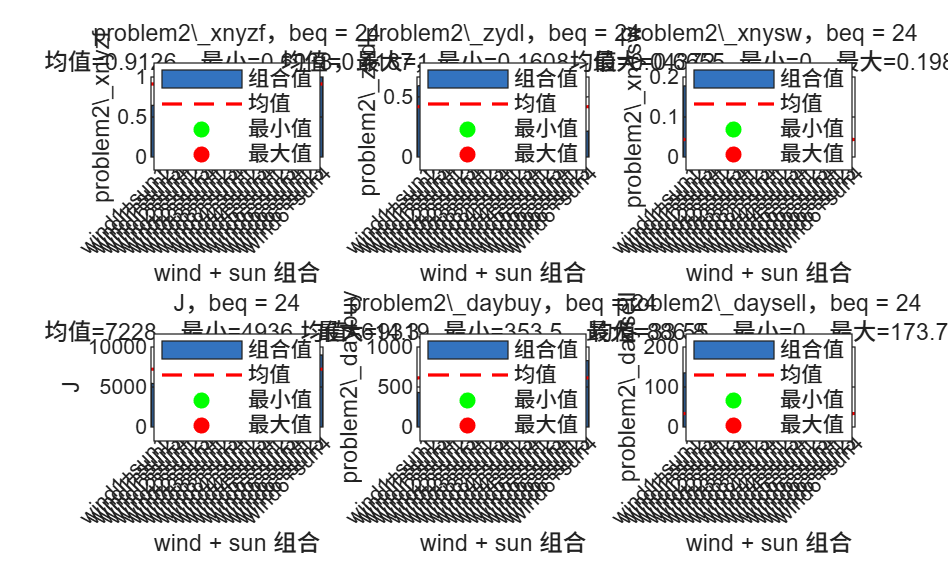

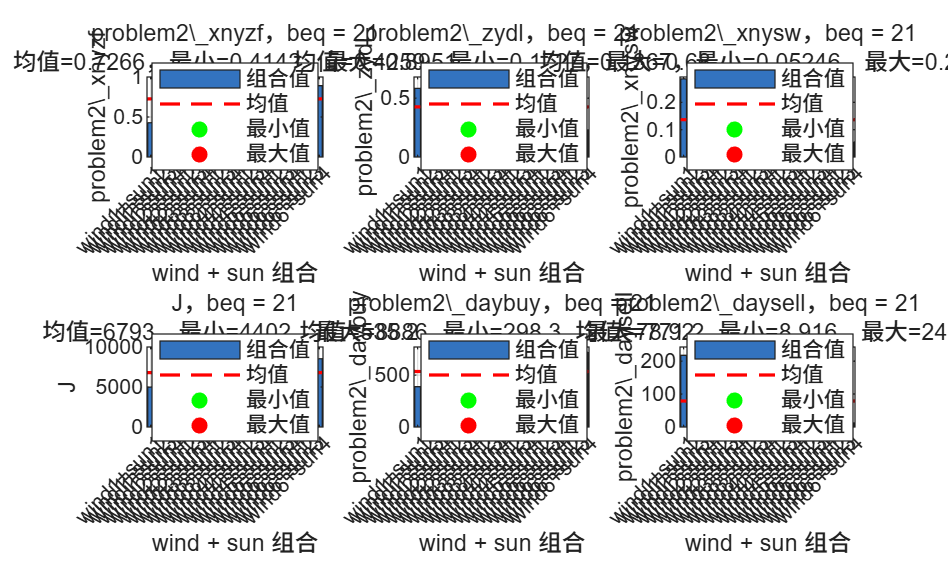

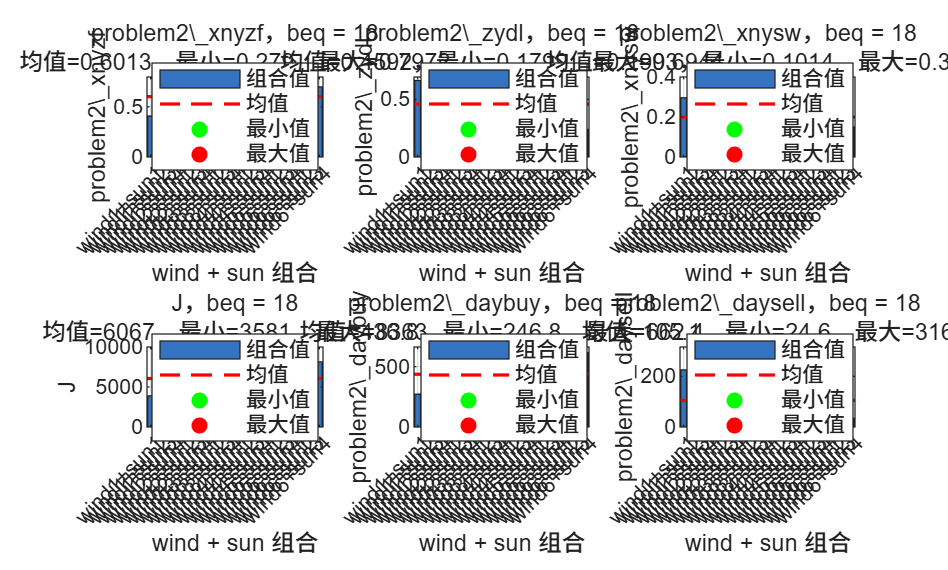

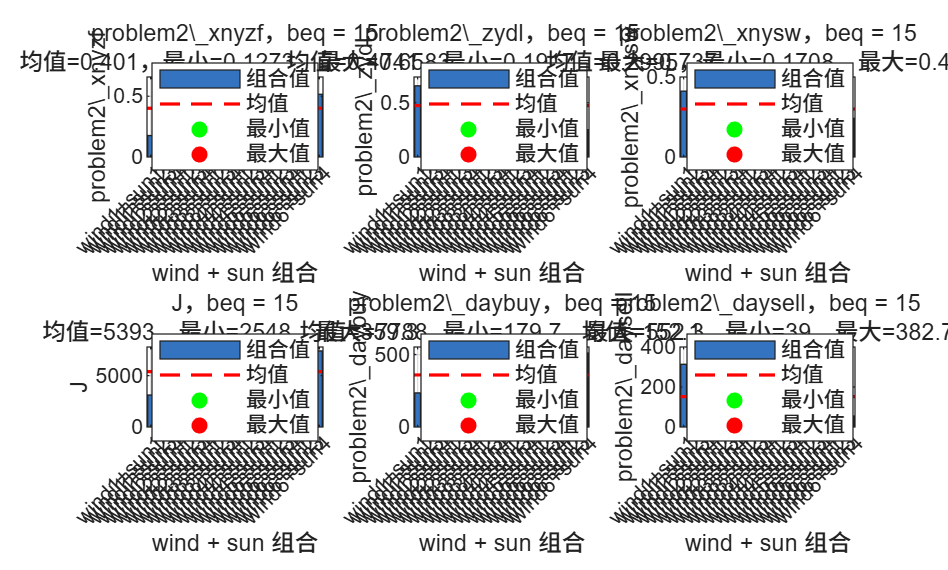

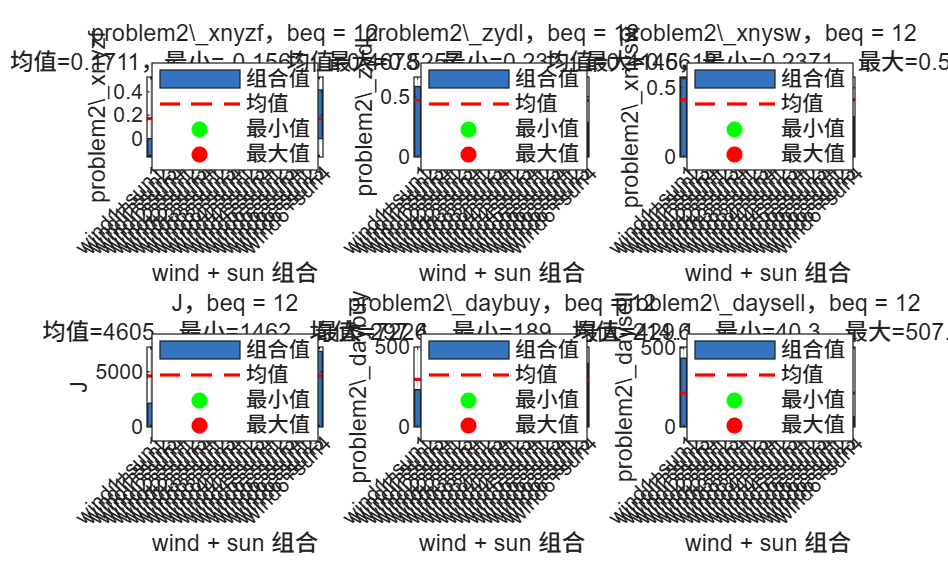


plotProblem2Distributions(problem2_results, beq_values);


function metrics = calcProblem2Metrics(t, classicload, wind, sun, fenshijijia )
                                     
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    metrics.nh3load = t*20.75*2;
    metrics.load = classicload*6 + metrics.nh3load;
    metrics.generate = wind*40 + sun*64;
    metrics.buy = metrics.load - metrics.generate;
    metrics.sell = metrics.buy;
    metrics.buy(metrics.buy<0) = 0;
    metrics.sell(metrics.sell>0) = 0;
    metrics.buycost = sum(metrics.buy .* fenshijijia);
    metrics.dayload = sum(metrics.load);
    metrics.daygenerate = sum(metrics.generate);
    metrics.daybuy = sum(metrics.buy);
    metrics.daysell = abs(sum(metrics.sell));

    % 保持原文件的指标计算方式

    metrics.xnyzf = (metrics.dayload-metrics.daysell-metrics.daybuy)/metrics.daygenerate;
    metrics.zydl = (metrics.daygenerate-metrics.daysell)/metrics.dayload;
    metrics.xnysw = metrics.daysell/metrics.daygenerate;
end


function plotProblem2Distributions(problem2_results, beq_values)
    metric_fields = {'xnyzf', 'zydl', 'xnysw', 'J_min', 'daybuy', 'daysell'};
    metric_names = {'problem2\_xnyzf', 'problem2\_zydl', 'problem2\_xnysw', ...
                    'J', 'problem2\_daybuy', 'problem2\_daysell'};

    for beq_idx = 1:numel(beq_values)
        beq = beq_values(beq_idx);
        beq_mask = [problem2_results.beq] == beq;
        beq_results = problem2_results(beq_mask);

        if isempty(beq_results)
            warning('beq = %g 没有可绘制的结果。', beq);
            continue;
        end

        sort_keys = [[beq_results.wind_idx]', [beq_results.sun_idx]'];
        [~, order] = sortrows(sort_keys, [1 2]);
        beq_results = beq_results(order);

        combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                                beq_results, 'UniformOutput', false);

        figure('Name', sprintf('beq=%g 下 24 种 wind/sun 组合指标分布', beq), ...
               'Color', 'w');

        for metric_idx = 1:numel(metric_fields)
            metric_field = metric_fields{metric_idx};
            metric_name = metric_names{metric_idx};
            values = arrayfun(@(r) r.(metric_field), beq_results);

            subplot(2, 3, metric_idx);
            bar(values, 'FaceColor', [0.2 0.45 0.75]);
            grid on;
            hold on;

            valid_values = values(~isnan(values));
            mean_value = mean(valid_values);
            min_value = min(valid_values);
            max_value = max(valid_values);
            [~, min_idx] = min(values);
            [~, max_idx] = max(values);

            plot(xlim, [mean_value mean_value], 'r--', 'LineWidth', 1.2);
            scatter(min_idx, min_value, 45, 'g', 'filled');
            scatter(max_idx, max_value, 45, 'r', 'filled');

            title({sprintf('%s，beq = %g', metric_name, beq), ...
                   sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
                           mean_value, min_value, max_value)}, ...
                  'Interpreter', 'none');
            xlabel('wind + sun 组合');
            ylabel(metric_name, 'Interpreter', 'none');
            set(gca, 'XTick', 1:numel(combo_labels), ...
                     'XTickLabel', combo_labels, ...
                     'XTickLabelRotation', 45);
            xlim([0.5, numel(combo_labels) + 0.5]);

            if min_value == max_value
                ylim([min_value - 0.5, max_value + 0.5]);
            end

            legend({'组合值', '均值', '最小值', '最大值'}, ...
                   'Location', 'best', 'FontSize', 8);
            hold off;
        end
    end
end

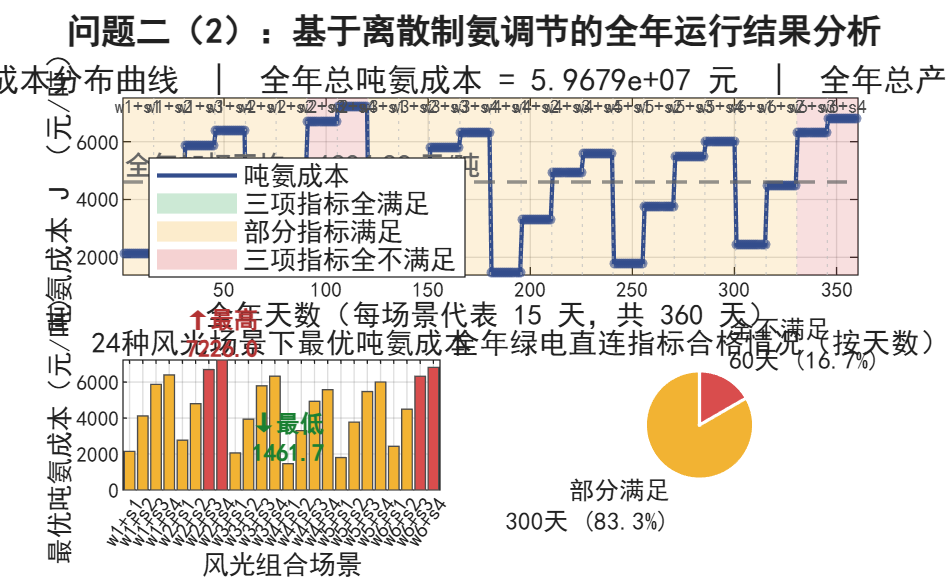

%% ========== 问题二(2) 全年吨氨成本分布曲线绘制 ==========
% 依赖：problem2_results（24种风光场景 × 5种产量 = 120条记录）
% 必须先跑过 24 场景的那段循环（含 wind_vectors / sun_vectors 的双层循环）

assert(exist('problem2_results','var')==1, 'problem2_results 不存在');

% 兼容性检查：必须有 24*5=120 条记录
n_records = numel(problem2_results);
if n_records ~= 120
    error(['problem2_results 当前有 %d 条记录，期望 120 条（24场景×5产量）。\n' ...
           '请先运行 24 种 wind+sun 组合的双层循环优化代码。'], n_records);
end

% 字段兼容：老版本可能没有 wind_idx/sun_idx，从 case_idx 反推
fns = fieldnames(problem2_results);
if ~ismember('wind_idx', fns)
    % case_idx 排列顺序：外层 wind 1..6，内层 sun 1..4，每个组合下 5 个 beq
    % 即第 k 条记录的 (wind_idx, sun_idx, beq_idx)：
    %   wind_idx = floor((k-1)/(4*5)) + 1
    %   sun_idx  = mod(floor((k-1)/5), 4) + 1
    for k = 1:n_records
        problem2_results(k).wind_idx = floor((k-1)/(4*5)) + 1;
        problem2_results(k).sun_idx  = mod(floor((k-1)/5), 4) + 1;
        problem2_results(k).wind_name = sprintf('wind%d', problem2_results(k).wind_idx);
        problem2_results(k).sun_name  = sprintf('sun%d',  problem2_results(k).sun_idx);
    end
    warning('problem2_results 中无 wind_idx 字段，已按 case_idx 顺序自动补齐。请核对场景顺序是否为 wind 外层、sun 内层。');
end

%% --- 1. 数据整理 ---
all_wind_idx = [problem2_results.wind_idx];
all_sun_idx  = [problem2_results.sun_idx];

n_wind = max(all_wind_idx);   % 6
n_sun  = max(all_sun_idx);    % 4
n_scen = n_wind * n_sun;      % 24
days_per_scen = 15;
n_days_year   = n_scen * days_per_scen;   % 360

best_J        = zeros(n_scen,1);
best_beq      = zeros(n_scen,1);
best_xnyzf    = zeros(n_scen,1);
best_zydl     = zeros(n_scen,1);
best_xnysw    = zeros(n_scen,1);
best_label    = strings(n_scen,1);
best_prod_ton = zeros(n_scen,1);

beq_to_ton = @(b) b * 1.5 * 2;   % 日产氨吨数 = sum(t)*1.5*2

scen_id = 0;
for wi = 1:n_wind
    for si = 1:n_sun
        scen_id = scen_id + 1;
        mask = (all_wind_idx==wi) & (all_sun_idx==si);
        sub = problem2_results(mask);
        if isempty(sub)
            error('场景 wind%d+sun%d 在 problem2_results 中找不到记录', wi, si);
        end
        [J_min_val, k] = min([sub.J_min]);
        best_J(scen_id)     = J_min_val;
        best_beq(scen_id)   = sub(k).beq;
        best_xnyzf(scen_id) = sub(k).xnyzf;
        best_zydl(scen_id)  = sub(k).zydl;
        best_xnysw(scen_id) = sub(k).xnysw;
        best_label(scen_id) = sprintf('w%d+s%d', wi, si);
        best_prod_ton(scen_id) = beq_to_ton(sub(k).beq);
    end
end

% 绿电指标合格性
ok_xnyzf = best_xnyzf > 0.60;
ok_zydl  = best_zydl  > 0.30;
ok_xnysw = best_xnysw < 0.20;
ok_all   = ok_xnyzf & ok_zydl & ok_xnysw;
n_pass_each = [ok_xnyzf, ok_zydl, ok_xnysw];
n_pass      = sum(n_pass_each, 2);   % 每个场景通过几项（0/1/2/3）
ok_part     = (n_pass>=1) & (n_pass<=2);
ok_none     = (n_pass==0);

n_full = sum(ok_all);  n_part = sum(ok_part);  n_none = sum(ok_none);

%% --- 2. 全年序列 ---
year_J     = repelem(best_J,        days_per_scen);
year_prod  = repelem(best_prod_ton, days_per_scen);

total_year_cost = sum(year_J .* year_prod);
total_year_ton  = sum(year_prod);
avg_year_cost   = total_year_cost / total_year_ton;

%% --- 3. 绘图 ---
fig = figure('Name','问题二(2) 全年吨氨成本分布','Color','w',...
             'Position',[100 100 1280 780]);
set(fig,'DefaultAxesFontName','SimHei','DefaultTextFontName','SimHei');

c_full = [0.20 0.65 0.35];
c_part = [0.95 0.70 0.20];
c_none = [0.85 0.30 0.30];
c_line = [0.20 0.30 0.55];

% ---- 子图1：全年吨氨成本分布曲线 ----
ax1 = subplot(2,2,[1 2]); hold(ax1,'on'); grid(ax1,'on'); box(ax1,'on');

x = 1:n_days_year;
y_lo = min(year_J)*0.95;  y_hi = max(year_J)*1.05;

for s = 1:n_scen
    x_start = (s-1)*days_per_scen + 0.5;
    x_end   =  s   *days_per_scen + 0.5;
    if ok_all(s),       fc = c_full;
    elseif ok_part(s),  fc = c_part;
    else,               fc = c_none;
    end
    patch(ax1,[x_start x_end x_end x_start], ...
          [y_lo y_lo y_hi y_hi], ...
          fc,'FaceAlpha',0.18,'EdgeColor','none','HandleVisibility','off');
end

plot(ax1, x, year_J, '-', 'Color', c_line, 'LineWidth', 1.6);
scatter(ax1, x, year_J, 14, c_line, 'filled', 'MarkerFaceAlpha', 0.6, 'HandleVisibility','off');

yline(ax1, avg_year_cost, '--', sprintf('全年加权平均 = %.2f 元/吨', avg_year_cost), ...
      'Color',[0.4 0.4 0.4], 'LineWidth', 1.3, ...
      'LabelHorizontalAlignment','left','FontSize', 10);

for s = 1:n_scen-1
    xline(ax1, s*days_per_scen+0.5, ':', 'Color',[0.75 0.75 0.75], 'HandleVisibility','off');
end

% 在每个场景顶部标注组合名
for s = 1:n_scen
    text(ax1, (s-0.5)*days_per_scen+0.5, y_hi*0.995, best_label(s), ...
        'HorizontalAlignment','center','VerticalAlignment','top', ...
        'FontSize',7,'Color',[0.3 0.3 0.3]);
end

xlabel(ax1,'全年天数（每场景代表 15 天，共 360 天）','FontSize',11);
ylabel(ax1,'吨氨成本 J （元/吨）','FontSize',11);
title(ax1, sprintf('园区全年吨氨成本分布曲线  |  全年总吨氨成本 = %.4e 元  |  全年总产量 = %.1f 吨', ...
       total_year_cost, total_year_ton), 'FontSize',12);
xlim(ax1,[0.5 n_days_year+0.5]);
ylim(ax1,[y_lo y_hi]);

h1 = patch(nan,nan,c_full,'FaceAlpha',0.25,'EdgeColor','none');
h2 = patch(nan,nan,c_part,'FaceAlpha',0.25,'EdgeColor','none');
h3 = patch(nan,nan,c_none,'FaceAlpha',0.25,'EdgeColor','none');
h4 = plot(ax1,nan,nan,'-','Color',c_line,'LineWidth',1.6);
legend(ax1,[h4 h1 h2 h3], ...
       {'吨氨成本','三项指标全满足','部分指标满足','三项指标全不满足'}, ...
       'Location','best','FontSize',10);

% ---- 子图2：24场景最优吨氨成本柱状图 ----
ax2 = subplot(2,2,3); hold(ax2,'on'); grid(ax2,'on'); box(ax2,'on');
bar_colors = repmat(c_part,n_scen,1);
bar_colors(ok_all,:)  = repmat(c_full, n_full, 1);
bar_colors(ok_none,:) = repmat(c_none, n_none, 1);

b = bar(ax2, 1:n_scen, best_J, 'FaceColor','flat','EdgeColor',[0.3 0.3 0.3]);
b.CData = bar_colors;

[J_lo, i_lo] = min(best_J);
[J_hi, i_hi] = max(best_J);
text(ax2, i_lo, J_lo, sprintf('↓最低\n%.1f', J_lo), ...
     'HorizontalAlignment','center','VerticalAlignment','bottom',...
     'FontSize',9,'Color',[0.1 0.5 0.2],'FontWeight','bold');
text(ax2, i_hi, J_hi, sprintf('↑最高\n%.1f', J_hi), ...
     'HorizontalAlignment','center','VerticalAlignment','bottom',...
     'FontSize',9,'Color',[0.7 0.2 0.2],'FontWeight','bold');

set(ax2,'XTick',1:n_scen,'XTickLabel',cellstr(best_label),...
    'XTickLabelRotation',55,'FontSize',8);
xlabel(ax2,'风光组合场景','FontSize',10);
ylabel(ax2,'最优吨氨成本（元/吨）','FontSize',10);
title(ax2,'24种风光场景下最优吨氨成本','FontSize',11);
xlim(ax2,[0.5 n_scen+0.5]);

% ---- 子图3：合格情况饼图 ----
ax3 = subplot(2,2,4);
days_full = n_full * days_per_scen;
days_part = n_part * days_per_scen;
days_none = n_none * days_per_scen;
pie_data   = [days_full, days_part, days_none];
pie_labels = {sprintf('全满足\n%d天 (%.1f%%)', days_full, days_full/n_days_year*100), ...
              sprintf('部分满足\n%d天 (%.1f%%)', days_part, days_part/n_days_year*100), ...
              sprintf('全不满足\n%d天 (%.1f%%)', days_none, days_none/n_days_year*100)};
valid = pie_data > 0;
colors_pie = [c_full; c_part; c_none];
colors_pie = colors_pie(valid,:);
ph = pie(ax3, pie_data(valid), pie_labels(valid));
patches_idx = 1;
for kk = 1:numel(ph)
    if isa(ph(kk),'matlab.graphics.primitive.Patch')
        ph(kk).FaceColor = colors_pie(patches_idx,:);
        ph(kk).EdgeColor = 'w';
        ph(kk).LineWidth = 1.2;
        patches_idx = patches_idx + 1;
    elseif isa(ph(kk),'matlab.graphics.primitive.Text')
        ph(kk).FontSize = 9.5;
        ph(kk).FontName = 'SimHei';
    end
end
title(ax3,'全年绿电直连指标合格情况（按天数）','FontSize',11);

sgtitle('问题二（2）：基于离散制氨调节的全年运行结果分析','FontSize',13,'FontWeight','bold');


%% --- 4. 控制台汇总 ---
fprintf('\n========== 问题二(2) 全年统计汇总 ==========\n');


========== 问题二(2) 全年统计汇总 ==========


fprintf('全年天数         : %d 天（24场景 × 15天）\n', n_days_year);

全年天数         : 360 天（24场景 × 15天）


fprintf('全年总产氨量     : %.2f 吨\n', total_year_ton);

全年总产氨量     : 12960.00 吨


fprintf('全年总吨氨成本   : %.4e 元\n', total_year_cost);

全年总吨氨成本   : 5.9679e+07 元


fprintf('全年加权平均成本 : %.2f 元/吨\n', avg_year_cost);

全年加权平均成本 : 4604.89 元/吨


fprintf('最低吨氨成本场景 : %s ，J = %.2f 元/吨\n', best_label(i_lo), J_lo);

最低吨氨成本场景 : w4+s1 ，J = 1461.72 元/吨


fprintf('最高吨氨成本场景 : %s ，J = %.2f 元/吨\n', best_label(i_hi), J_hi);

最高吨氨成本场景 : w2+s4 ，J = 7225.96 元/吨


fprintf('绿电指标 全满足  : %d 场景 / %d 天 (%.1f%%)\n', n_full, days_full, days_full/n_days_year*100);

绿电指标 全满足  : 0 场景 / 0 天 (0.0%)


fprintf('绿电指标 部分满足: %d 场景 / %d 天 (%.1f%%)\n', n_part, days_part, days_part/n_days_year*100);

绿电指标 部分满足: 20 场景 / 300 天 (83.3%)


fprintf('绿电指标 全不满足: %d 场景 / %d 天 (%.1f%%)\n', n_none, days_none, days_none/n_days_year*100);

绿电指标 全不满足: 4 场景 / 60 天 (16.7%)



T = table((1:n_scen)', best_label, best_prod_ton, best_beq, best_J, ...
          best_xnyzf, best_zydl, best_xnysw, ok_all, ...
    'VariableNames', {'场景','风光组合','日产氨_吨','sum_t','吨氨成本',...
                      '自发自用比','绿电占比','上网比','三项全合格'});
disp(T);

    场景    风光组合    日产氨_吨    sum_t    吨氨成本    自发自用比    绿电占比     上网比     三项全合格
    ____    _______    ________    _____    _______    _________    _______    _______    _________

      1     "w1+s1"       36        12      2147.1      -0.14538     0.5826    0.57269      false  
      2     "w1+s2"       36        12      4118.6       0.17733    0.53017    0.41134      false  
      3     "w1+s3"       36        12      5872.2       0.19578     0.3611    0.40211      false  
      4     "w1+s4"       36        12      6396.5       0.40873    0.34392    0.29563      false  
      5     "w2+s1"       36        12      2769.7      -0.10317    0.52882    0.55158      false  
      6     "w2+s2"       36        12      4795.8       0.30022    0.46583    0.34989      false  
      7     "w2+s3"       36        12      6696.7       0.19377    0.25061    0.40312      false  
      8     "w2+s4"       36        12        7226       0.52574    0.23204    0.23713      false  
      9     "w3+s1"    